# Plot the Poynting vector in Fourier space of the SFG scattered field

ans = 4.1668e-06

ans = 2.9280e-13

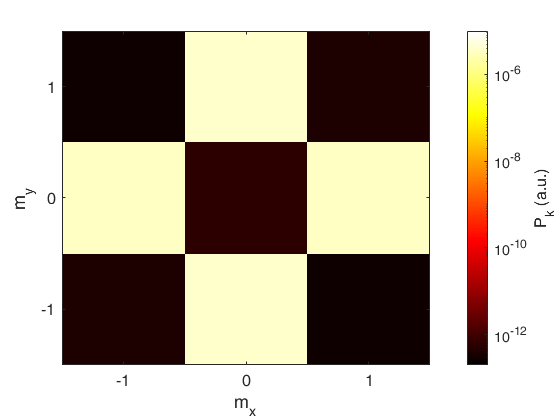

ans = 1.1244e-05

ans = 2.5775e-13

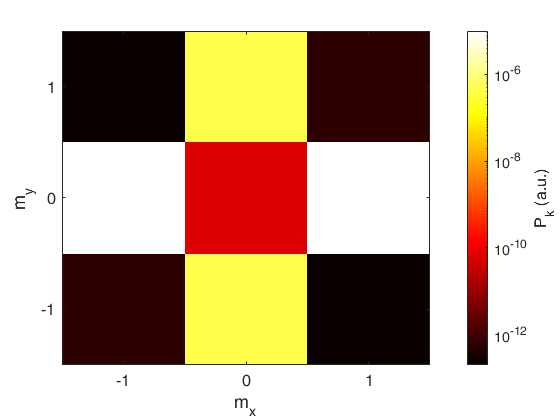

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis'));
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed'));
% {
job = "cylinder_dimer_no_substrate_110_2";
freq_num = [26 26 26 26 26 26 26 26 26];
%}
%{
job = "cylinder_dimer_no_substrate_111_6";
freq_num = [233   232   229   224   216   207   196   182];
%}
%{
job = "cylinder_dimer_no_substrate_110_2";
freq_num = [26 26];
%}
eval(job);
load([options.output_dir_final 'sweep_data.mat']);
extra_options = matthew_extra_options(options);

for sweep_num = 1:height(sweep_data)
    
    sum_fft = sweep_data(sweep_num,:).SumFFT{1};
    derived_values = sweep_data(sweep_num,:).DerivedValues{1};
    denom = derived_values.parameters.I0*derived_values.parameters.I0_i;
    
    for cut_plane_index = 1:length(extra_options.cut_plane)
        for direction = extra_options.direction
            
            [FTx, FTy, FTz,FThx, FThy, FThz, FTpoynting] = ...
                matthew_get_fft_of_cut_plane(sum_fft, ...
                extra_options.cut_plane(cut_plane_index), direction, ...
                freq_num(sweep_num));
            
            for FT_num = 5%1:5
                switch FT_num
                    case 1
                        FTxyz = FTx;
                        FThxyz = FThx;
                    case 2
                        FTxyz = FTy;
                        FThxyz = FThy;
                    case 3
                        FTxyz = FTz;
                        FThxyz = FThz;
                    case 4
                        FTxyz = abs(FTx).^2 + abs(FTy).^2;
                        FThxyz = abs(FThx).^2 + abs(FThy).^2;
                    otherwise
                        FTxyz = FTpoynting;
                end
                    
                [X,Y] = meshgrid(...
                    -2/pi-4/(pi*(length(FTxyz)-1)):4/(pi*(length(FTxyz)-1)):...
                            2/pi-4/(pi*(length(FTxyz)-1)),...
                    -2/pi-4/(pi*(length(FTxyz)-1)):4/(pi*(length(FTxyz)-1)):...
                            2/pi-4/(pi*(length(FTxyz)-1)));
                        
                figure;
                imagesc(abs(FTxyz)/denom);
                set(gca, 'FontSize', 12);
                max(max(abs(FTxyz)/denom))
                min(min(abs(FTxyz)/denom))
                view(0,-90);
                xlabel('m_x', 'FontSize', 12)
                ylabel('m_y', 'FontSize', 12)
                xticks([1 2 3]);
                xticklabels({'-1','0','1'});
                yticks([1 2 3]);
                yticklabels({'-1','0','1'});
                cb = colorbar;
                set(gca,'ColorScale','log');
                ylabel(cb, 'P_k (a.u.)', 'FontSize', 12);
                colormap parula;
                switch FT_num
                    case 1
                        title('|FFT(E_x)|');
                    case 2
                        title('|FFT(E_y)|');
                    case 3
                        title('|FFT(E_z)|');
                    case 4
                        title('|FFT(E_x)|^2+|E_y|^2');
                    otherwise
                        %{
                        title({job, strcat("phi = ",...
                            sweep_data(sweep_num,:).phi, ", orientation_xy = ",...
                            sweep_data(sweep_num,:).orientation_xy)},...
                            'Interpreter', 'none');
                        %}
                        %{
                        title({job, strcat("theta = ",...
                            sweep_data(sweep_num,:).theta)}, 'Interpreter', 'none');
                        %}
                end
                colormap hot;
                %axis tight;
                caxis([2.01e-13 9.98e-6]);
            end
        end
    end
end